# **Homework 2 Sol. (OCDR)**

**Universidad Nacional de Colombia**

**By:**

- Santiago Cadena Álvarez (Electrical Engineering student)

**To: **

Eng. Eduardo A. Mojica - Nava

## **1) Consensus Protocol: Continuous-time**

Construct a connected graph of 10 nodes with ramdon structure, i.e., the links are randomly selected, but the graph should not be fully connected.

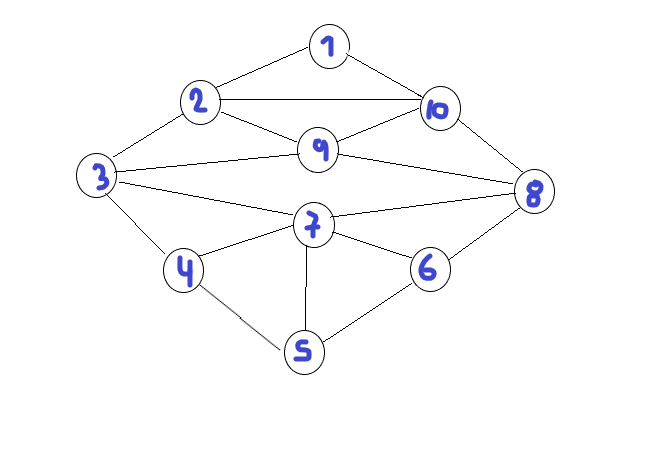

1. Derive the consensus equation. Show the degree matrix, adjancency matrix, and Laplacian matrix, and then the full equation in matrix form.

The degree matrix is the matrix which has the node degrees of G inside the diagonal: 

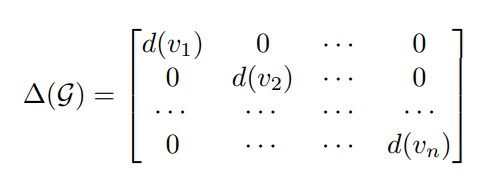


$$\Delta \left(G\right)=\left\lbrack \begin{array}{cccccccccc}
2 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 4 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 4 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 3 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 3 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 3 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 5 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 4 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 4 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 4
\end{array}\right\rbrack$$


The adjacency matrix is defined by 

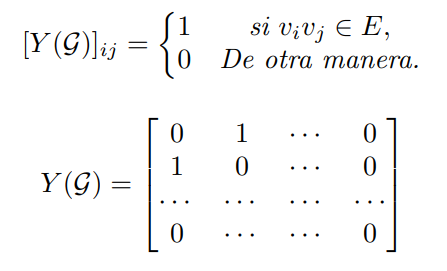 

where $v_i$ is the current node and$v_j$ is any of the adjacent nodes of $v_i$


$$Y\left(G\right)=\left\lbrack \begin{array}{cccccccccc}
0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
1 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 1\\
0 & 1 & 0 & 1 & 0 & 0 & 1 & 0 & 1 & 0\\
0 & 0 & 1 & 0 & 1 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 1 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 1 & 1 & 0 & 0\\
0 & 0 & 1 & 1 & 1 & 1 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 1 & 0 & 1 & 1\\
0 & 1 & 1 & 0 & 0 & 0 & 0 & 1 & 0 & 1\\
1 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 1 & 0
\end{array}\right\rbrack$$


The Laplacian is defined:


$$L\left(G\right)=\left\lbrack \begin{array}{cccccccccc}
2 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1\\
-1 & 4 & -1 & 0 & 0 & 0 & 0 & 0 & -1 & -1\\
0 & -1 & 4 & -1 & 0 & 0 & -1 & 0 & -1 & 0\\
0 & 0 & -1 & 3 & -1 & 0 & -1 & 0 & 0 & 0\\
0 & 0 & 0 & -1 & 3 & -1 & -1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -1 & 3 & -1 & -1 & 0 & 0\\
0 & 0 & -1 & -1 & -1 & -1 & 5 & -1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & -1 & 4 & -1 & -1\\
0 & -1 & -1 & 0 & 0 & 0 & 0 & -1 & 4 & -1\\
-1 & -1 & 0 & 0 & 0 & 0 & 0 & -1 & -1 & 4
\end{array}\right\rbrack$$


Then, the full equation form is:


$$\dot{x} =L\left(G\right)x$$



$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 \\
{\dot{x} }_3 \\
{\dot{x} }_4 \\
{\dot{x} }_5 \\
{\dot{x} }_6 \\
{\dot{x} }_7 \\
{\dot{x} }_8 \\
{\dot{x} }_9 \\
{\dot{x} }_{10} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccccccc}
2 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1\\
-1 & 4 & -1 & 0 & 0 & 0 & 0 & 0 & -1 & -1\\
0 & -1 & 4 & -1 & 0 & 0 & -1 & 0 & -1 & 0\\
0 & 0 & -1 & 3 & -1 & 0 & -1 & 0 & 0 & 0\\
0 & 0 & 0 & -1 & 3 & -1 & -1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -1 & 3 & -1 & -1 & 0 & 0\\
0 & 0 & -1 & -1 & -1 & -1 & 5 & -1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & -1 & 4 & -1 & -1\\
0 & -1 & -1 & 0 & 0 & 0 & 0 & -1 & 4 & -1\\
-1 & -1 & 0 & 0 & 0 & 0 & 0 & -1 & -1 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 \\
x_7 \\
x_8 \\
x_9 \\
x_{10} 
\end{array}\right\rbrack$$


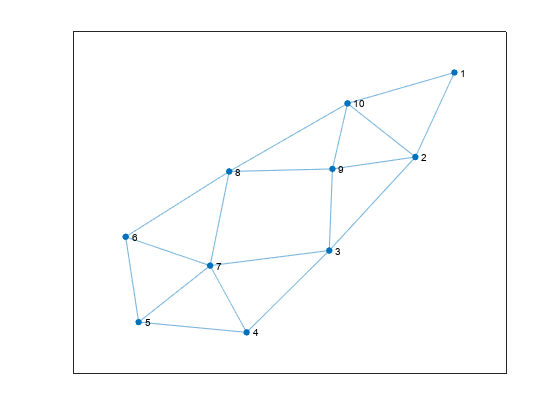

Y = [0, 1, 0, 0, 0, 0, 0, 0, 0, 1;
     1, 0, 1, 0, 0, 0, 0, 0, 1, 1;
     0, 1, 0, 1, 0, 0, 1, 0, 1, 0;
     0, 0, 1, 0, 1, 0, 1, 0, 0, 0;
     0, 0, 0, 1, 0, 1, 1, 0, 0, 0;
     0, 0, 0, 0, 1, 0, 1, 1, 0, 0;
     0, 0, 1, 1, 1, 1, 0, 1, 0, 0;
     0, 0, 0, 0, 0, 1, 1, 0, 1, 1;
     0, 1, 1, 0, 0, 0, 0, 1, 0, 1;
     1, 1, 0, 0, 0, 0, 0, 1, 1, 0];
G = graph(Y);
plot(G)

2. Plot using Matlab the eigenvalues and comment about the distribution of the nodes connectivity and the localization of the eigenvalues.

The eigen values and eigen vectors come from:


$$\begin{array}{l}
L\left(G\right)\vec{X} =\lambda \vec{X} \\
\left(L\left(G\right)-\lambda I\right)\vec{X} =0
\end{array}$$


Where $\lambda$ are the eigenvalues corresponding to the eigenvectores X

L= [2, -1, 0, 0, 0, 0, 0, 0, 0, -1;
    -1, 4, -1, 0, 0, 0, 0, 0, -1, -1;
     0, -1, 4, -1, 0, 0, -1, 0, -1, 0;
     0, 0, -1, 3, -1, 0, -1, 0, 0, 0;
     0, 0, 0, -1, 3, -1, -1, 0, 0, 0;
     0, 0, 0, 0, -1, 3, -1, -1, 0, 0;
     0, 0, -1, -1, -1, -1, 5, -1, 0, 0;
     0, 0, 0, 0, 0, 1, -1, 4, -1, -1;
     0, -1, -1, 0, 0, 0, 0, -1, 4, -1;
    -1, -1, 0, 0, 0, 0, 0, -1, -1, 4];

eigenvalues=eig(L)

eigenvalues =    0.185248195377493
   0.830505268473319
   6.515559835252567
   2.346825696196454
   5.657523380709324
   5.293968839647963
   4.757751628789638
   3.999999999999996
   3.000000000000007
   3.412617155553241


[eigenvectors,D]=eig(L)

eigenvectors =    0.360502184723704   0.357274292030795  -0.016704619018228   0.657037562663227   0.001609166798584   0.217811934578551   0.159557727115423   0.204124145231934  -0.377964473009226   0.284173663856725
   0.345549905134386   0.175595850058795   0.026268421068708  -0.082317505075289   0.568464036963871  -0.585694873300872   0.128608987839896  -0.408248290463863   0.188982236504615  -0.337908831149777
   0.343808056532594  -0.160912740552553  -0.401782986633406  -0.184733369620316  -0.388589806054431  -0.026091803635942   0.300098046068449   0.000000000000002  -0.000000000000001  -0.108343092812693
   0.351770616693913  -0.471037839118041  -0.037129063684675   0.235519161410847   0.192724080800564   0.111543863182473  -0.460658987772505   0.408248290463861  -0.566946709513841   0.537076371966851
   0.337321837125526  -0.528477257426240  -0.186011819592510   0.334337177790159   0.012600293074113  -0.039777696997530   0.416495949759492  -0.612372435695793   0.000000000000003 

D =    0.185248195377493                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0   0.830505268473319                   0                   0                   0                   0                   0                   0                   0                   0
                   0                   0   6.515559835252567                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0   2.346825696196454                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0   5.657523380709324                   0                   0                   0                   0            

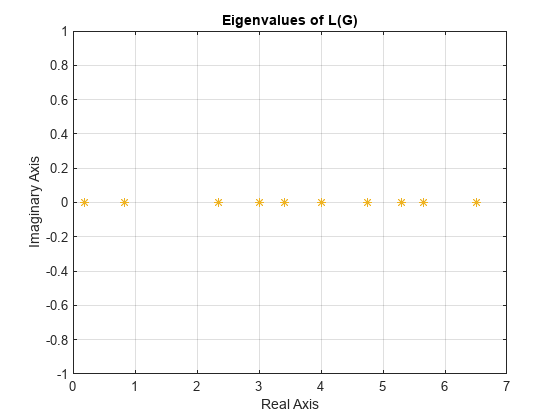

plot(eigenvalues,zeros(10),'*')
grid on;
ylabel('Imaginary Axis')
xlabel('Real Axis')
title('Eigenvalues of L(G)')

As the Laplacian of the graph L(G) is simetric and is defined semipositive, hence all of the the eigen values are real positive and can be ordered as:


$$\lambda_1 \le \lambda_2 \le \lambda_3 \le \ldotp \ldotp \ldotp \lambda_{10}$$


We see that's true. It also can be seen that the Fiedler Eigenvalue ($\lambda_2$) is positive and, therefore **the Graph** **is connected, **i.e that exist at least one way go from a node $v_i$ to any other node$v_j$ inside the graph. Since no node is zero, then there's no node appart from the others, or a component isolated from the rest. Finally, the substantial variation among the eigenvalues highlights marked distinctions, suggesting that certain nodes in the graph exhibit significantly stronger connections than others.

3. Simulate the consensus protocol with distributed initial conditions from the interval I = [−5 5]. What is the agreement set? Obtain the time constant of the consensus equation and verify it in a plot of the time response (${x\;}_i \;\textrm{vs}\;t,\forall i$) 

In continuous time, the solution of the system of lineal equations of first order is :


$$x\left(t\right)=e^{-L\left(G\right)t} x_0$$


Since this cannot be computed in matlab this way given that L(G) is a matrix, i will use a function solver named 'ode45' which resolves differential equations using the intermediate method. 


% First, it's necessary to define the time span:
tspan = [0, 20]; %t in seconds

% Number of nodes (10)
n = size(L, 1);

% Generate distributed initial conditions randomly in the interval [-5, 5]
x0 = -5 + 10 * rand(n, 1);

% Define the consensus equation dx_i/dt = -L*x_i
consensus_equation = @(t, x) -L * x;

% Numerically simulate the consensus equation for each node
[t, x] = ode45(consensus_equation, tspan, x0);


The agreement set is defined as the set of nodes inside a graph that reach the concensus, i.e the nodes try to reach to a commoun value, obbiusly with a certain tolerance. In the code, I'm comparing the value of the last nodes states with the value of the last node state of the first node x1. Then if all of the last states are equal to the x1 last state, so the agreement set is reached.

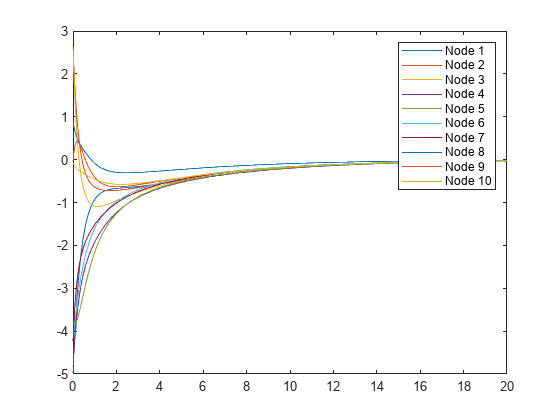

% Find the agreement set (nodes that reach consensus)
tolerance = 1e-3; 
if all(abs(x(end, :) - x(end, 1)) < tolerance)
    agreement_set=x(end,1) %0
end

% Plot the time response for each node
for i = 1:n
    plot(t, x(:, i));
    hold on;
end
legend('Node 1','Node 2','Node 3','Node 4','Node 5','Node 6','Node 7','Node 8','Node 9','Node 10');

It's showed that the constant is zero and it goes accordly to the theory:


$$\lim_{t\to \infty } x\left(t\right)=0$$


4. Add some weights and directions to the graph. You should guarantee that the new agreement protocol reach consensus. Explain what have you considered to guarantee convergence to an agreement set.x.

When there's a diagraph and it has unitary weights, then in the compact concencus problem we have to account the directions that enter into the node and the respectively weight.


$$\dot{x} =L\left(D\right)x$$


Stablishing a the weights and the directions arbitrary of this way:

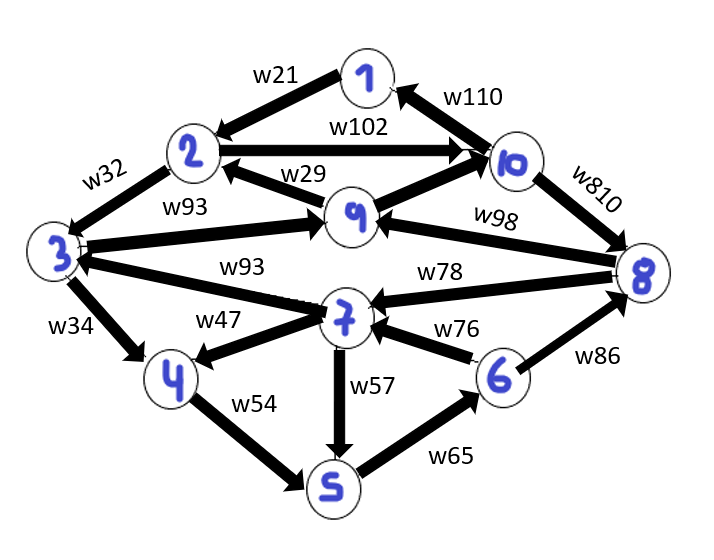

We have:


$$L\left(G\right)=\left\lbrack \begin{array}{cccccccccc}
w_{110}  & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -w_{110} \\
-w_{21}  & w_{21} +w_{29}  & 0 & 0 & 0 & 0 & 0 & 0 & {-w}_{29}  & 0\\
0 & -w_{32}  & w_{32} +w_{37}  & 0 & 0 & 0 & {-w}_{37}  & 0 & 0 & 0\\
0 & 0 & -w_{43}  & w_{43} +w_{47}  & 0 & 0 & {-w}_{47}  & 0 & 0 & 0\\
0 & 0 & 0 & -w_{54}  & w_{54} +w_{57}  & 0 & -w_{57}  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & {-w}_{65}  & w_{65}  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & {-w}_{76}  & w_{76} +w_{78}  & -w_{78}  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & -w_{86}  & 0 & w_{810} +w_{86}  & 0 & {-w}_{810} \\
0 & 0 & {-w}_{93}  & 0 & 0 & 0 & 0 & {-w}_{98}  & w_{93} +w_{98}  & 0\\
0 & {-w}_{102}  & 0 & 0 & 0 & 0 & 0 & 0 & -w_{910}  & w_{102} +w_{910} 
\end{array}\right\rbrack$$


Having in account the next theorem

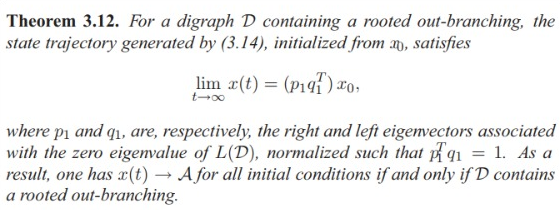

And the next propostion is accomplished:

Choosing arbitrary values 


$$L\left(G\right)=\left\lbrack \begin{array}{cccccccccc}
2 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -2\\
-3 & 8 & 0 & 0 & 0 & 0 & 0 & 0 & -5 & 0\\
0 & -4 & 7 & 0 & 0 & 0 & -3 & 0 & 0 & 0\\
0 & 0 & -8 & 17 & 0 & 0 & -9 & 0 & 0 & 0\\
0 & 0 & 0 & -2 & 5 & 0 & -3 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -1 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & -3 & 4 & -1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & -2 & 0 & 5 & 0 & -3\\
0 & 0 & -2 & 0 & 0 & 0 & 0 & -1 & 3 & 0\\
0 & -6 & 0 & 0 & 0 & 0 & 0 & 0 & -4 & 10
\end{array}\right\rbrack$$


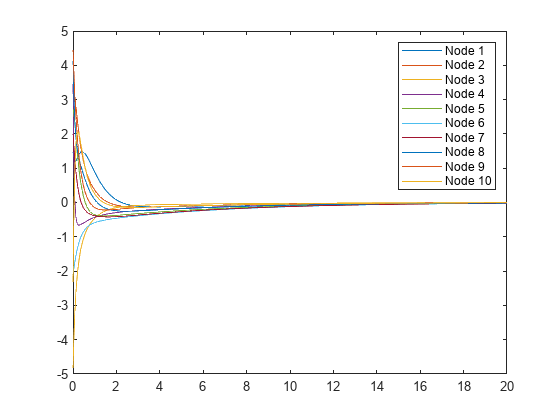

L = [2, 0, 0, 0, 0, 0, 0, 0, 0, -2;
    -3, 8, 0, 0, 0, 0, 0, 0, -5, 0;
    0, 4, 7, 0, 0, 0, -3, 0, 0, 0;
    0, 0, -8, 17, 0, 0, -9, 0, 0, 0;
    0, 0, 0, -2, 5, 0, -3, 0, 0, 0;
    0, 0, 0, 0, -1, 1, 0, 0, 0, 0;
    0, 0, 0, 0, 0, -3, 4, -1, 0, 0;
    0, 0, 0, 0, 0, -2, 0, 5, 0, -3;
    0, 0, -2, 0, 0, 0, 0, -1, 3, 0;
    0, -6, 0, 0, 0, 0, 0, 0, -4, 10];

% First, it's necessary to define the time span:
tspan = [0, 20]; %t in seconds
% Number of nodes (10)
n = size(L, 1);
% Generate distributed initial conditions randomly in the interval [-5, 5]
x0 = -5 + 10 * rand(n, 1);
% Define the consensus equation dx_i/dt = A*x_i (for graphs with direction and weights)
consensus_equation = @(t, x) -L * x;
% Numerically simulate the consensus equation for each node
[t, x] = ode45(consensus_equation, tspan, x0);
% Plot the time response for each node
figure
for i = 1:n
    plot(t, x(:, i));
    hold on;
end
legend('Node 1','Node 2','Node 3','Node 4','Node 5','Node 6','Node 7','Node 8','Node 9','Node 10');


eig(L)

ans =  17.014942188626346 + 0.000000000000000i
  0.162342442784495 + 0.000000000000000i
  1.858043480922473 + 0.000000000000000i
  2.234560216834665 + 0.000000000000000i
  4.537613725679439 + 2.588743730168143i
  4.537613725679439 - 2.588743730168143i
  9.140024164438959 + 0.199568343655513i
  9.140024164438959 - 0.199568343655513i
  6.687417945297618 + 0.316569180684525i
  6.687417945297618 - 0.316569180684525i


As the previous exercise, the eigenvalues are all positive and the rank is 10, that is to say that the maximum number of columns are lineary independent.

## **1) Consensus Protocol: Discrete - Time**

Consider an undirected graph of 7 nodes (no fully connected) as your network of agents.

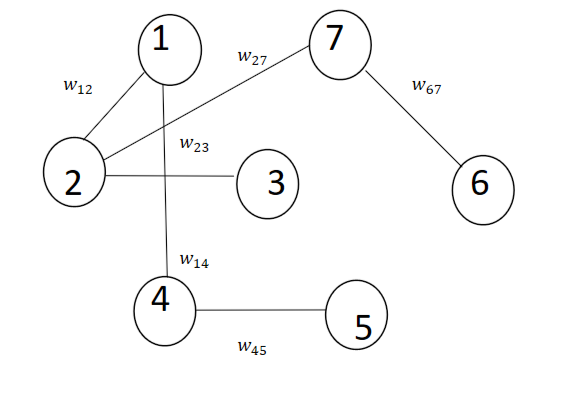

1. Find a weighted matrix satisfying the assumptions for convergence (doubly-stochastic, positive entries, etc.)

**a)** Each A(t) is a **stochastic** matrix what is compliant with the graph $G_t$ i.e: ${\mathrm{A}}_{\textrm{ij}} >0\;\textrm{for}\;\left(j,i\right)\in E_t$ for all t.

**b) (Aperiodicity) **The diagonal entries of each A(t) are positive,  ${\mathrm{A}}_{\textrm{ii}} \left(t\right)>0\;\textrm{for}\;t\;\textrm{and}\;i\in V\;$

**c) (Uniform Positivity)** There is a scalar β > 0 such that ${\mathrm{A}}_{\textrm{ij}} \left(t\right)>\beta$ whenever ${\mathrm{A}}_{\textrm{ij}} \left(t\right)>0$

**d) (Irreducibility)** Each graph $G_t$ is strongly connected. 

The Laplacian is:


$$L=\left\lbrack \begin{array}{ccccccc}
w_{12} +w_{14}  & -w_{12}  & 0 & {-w}_{14}  & 0 & 0 & 0\\
-w_{12}  & w_{12} +w_{23} +w_{27}  & {-w}_{23}  & 0 & 0 & 0 & -w_{27} \\
0 & -w_{23}  & w_{23}  & 0 & 0 & 0 & 0\\
{-w}_{14}  & 0 & 0 & w_{14} +w_{45}  & -w_{45}  & 0 & 0\\
0 & 0 & 0 & -w_{45}  & w_{45}  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & w_{67}  & {-w}_{67} \\
0 & {-w}_{27}  & 0 & 0 & 0 & {-w}_{67}  & w_{67} +w_{27} 
\end{array}\right\rbrack$$



$$A=\left(I-\alpha L\right)$$



$$A=\left\lbrack \begin{array}{ccccccc}
1-\alpha \left(w_{12} +w_{14} \right) & \alpha w_{12}  & 0 & {\alpha w}_{14}  & 0 & 0 & 0\\
\alpha w_{12}  & 1-\alpha \left(w_{12} +w_{23} +w_{27} \right) & \alpha w_{23}  & 0 & 0 & 0 & \alpha w_{27} \\
0 & \alpha w_{23}  & {1-\alpha w}_{23}  & 0 & 0 & 0 & 0\\
\alpha w_{14}  & 0 & 0 & 1-\alpha \left(w_{14} +w_{45} \right) & \alpha w_{45}  & 0 & 0\\
0 & 0 & 0 & {\alpha w}_{45}  & 1-\alpha w_{45}  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1-\alpha w_{67}  & {\alpha w}_{67} \\
0 & \alpha w_{27}  & 0 & 0 & 0 & \alpha w_{67}  & 1-\alpha \left(w_{67} +w_{27} \right)
\end{array}\right\rbrack$$


We see that the matrix is already stochastic by rows and stochastic by columns independent of the $\alpha$ value and the weights. 

To acomplish the first 3 assumptions **a) b) and c)** of the matrix, all of the elements of the matrix must be grater than 0. So choosing $\alpha =\frac{1}{7},$we have:


$$w_{67} <\frac{1}{\alpha }\to w_{67} =4$$



$$w_{27} <\frac{1}{\alpha }-w_{27} \to w_{27} =1$$



$$w_{45} <\frac{1}{\alpha }\to w_{45} =1$$



$$w_{14} <\frac{1}{\alpha }-w_{45} \to w_{14} =5$$



$$w_{23} <\frac{1}{\alpha }\to w_{23} =4$$



$$w_{12} <\frac{1}{\alpha }-w_{14} \to w_{12} =0\ldotp 5$$



$$A=\left\lbrack \begin{array}{ccccccc}
\frac{3}{14} & \frac{1}{14} & 0 & \frac{5}{7} & 0 & 0 & 0\\
\frac{1}{14} & \frac{1}{14} & \frac{4}{7} & 0 & 0 & 0 & \frac{1}{7}\\
0 & \frac{4}{7} & \frac{3}{7} & 0 & 0 & 0 & 0\\
\frac{5}{7} & 0 & 0 & \frac{1}{7} & \frac{1}{7} & 0 & 0\\
0 & 0 & 0 & \frac{1}{7} & \frac{6}{7} & 0 & 0\\
0 & 0 & 0 & 0 & 0 & \frac{3}{7} & \frac{4}{7}\\
0 & \frac{1}{7} & 0 & 0 & 0 & \frac{4}{7} & \frac{2}{7}
\end{array}\right\rbrack$$


And at last, the irreducibility **d)** is fulfilled, as there exists a path from every node to reach any other node in the graph.

2. Consider a scalar state x ∈ R, propose a consensus protocol in discrete-time  or some initial conditions. Analyze the convergence from a theoretical point of view and in simulation (implement the protocol using Matlab (or Python) and show the results).

Beacause the ireative process is distributed according to the local agent. Also the algorithm will converge, but it´s tricky to find the rate of conversion due to it depends on the weight matrix A, and the conversion depends on the in A as well.

From the theorical point of view, the solution converges when it satisfies the following:


$$\lim_{n\to \infty } \;A^n =\textrm{constant}$$


As the elements of the matrix are all smaller than 1, so this limit it's true and therefore the solution converges. Also all of the eigenvalues acomplish the Ruth Hurwitz criterion ($|\lambda_i |$<1) for completely convergence.

A = [3/14, 1/14, 0, 5/7, 0, 0, 0;
     1/14, 1/14, 4/7, 0, 0, 0, 1/7;
     0, 4/7, 3/7, 0, 0, 0, 0;
     5/7, 0, 0, 1/7, 1/7, 0, 0;
     0, 0, 0, 1/7, 6/7, 0, 0;
     0, 0, 0, 0, 0, 3/7, 4/7;
     0, 1/7, 0, 0, 0, 4/7, 2/7];
A^inf %0

ans =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


eig(A) %<1

ans =   -0.553800448901036
  -0.388942395378279
  -0.179263771239329
   0.773166785427477
   0.829678311361490
   0.960119319080658
   0.987613628220448


3. Consider the same graph but with directed edges having a root-outbranching node. Find the consensus protocol and analyze the convergence from a theoretical point of view and in simulation (implement the protocol using Matlab (or Python) and show the results).

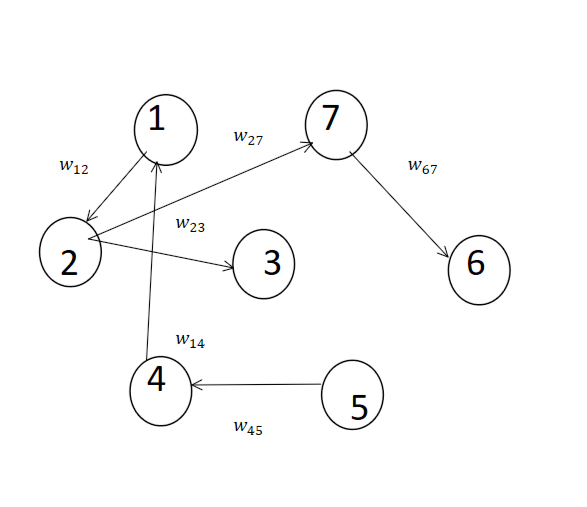

In this case the root out branching node is the node number 5.

The matrix L is:


$$L=\left\lbrack \begin{array}{ccccccc}
w_{14}  & 0 & 0 & {-w}_{14}  & 0 & 0 & 0\\
-w_{12}  & w_{12}  & 0 & 0 & 0 & 0 & 0\\
0 & -w_{23}  & w_{23}  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & w_{45}  & -w_{45}  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & w_{67}  & {-w}_{67} \\
0 & {-w}_{27}  & 0 & 0 & 0 & 0 & w_{27} 
\end{array}\right\rbrack$$



$$A=\left\lbrack \begin{array}{ccccccc}
{1-\alpha w}_{14}  & 0 & 0 & {\alpha w}_{14}  & 0 & 0 & 0\\
\alpha w_{12}  & 1-\alpha w_{12}  & 0 & 0 & 0 & 0 & 0\\
0 & \alpha w_{23}  & {1-\alpha w}_{23}  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & {1-\alpha w}_{45}  & \alpha w_{45}  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1-\alpha w_{67}  & {\alpha w}_{67} \\
0 & {\alpha w}_{27}  & 0 & 0 & 0 & 0 & {1-\alpha w}_{27} 
\end{array}\right\rbrack$$



$$A=\left\lbrack \begin{array}{ccccccc}
\frac{2}{7} & 0 & 0 & \frac{5}{7} & 0 & 0 & 0\\
\frac{1}{14} & \frac{13}{14} & 0 & 0 & 0 & 0 & 0\\
0 & \frac{4}{7} & \frac{3}{7} & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \frac{6}{7} & \frac{1}{7} & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & \frac{3}{7} & \frac{4}{7}\\
0 & \frac{1}{7} & 0 & 0 & 0 & 0 & \frac{6}{7}
\end{array}\right\rbrack$$



$$x\left\lbrack n+1\right\rbrack =\textrm{Ax}\left\lbrack n\right\rbrack$$


We see the matrix is stochastic in rows, but not in columns with the previouly values of $\alpha$ and the weights, it means that it reaches the semi-convergence, i.e that the value of the nodes could be near, but neccesary and not in all the cases.  We can verify this on simulation:

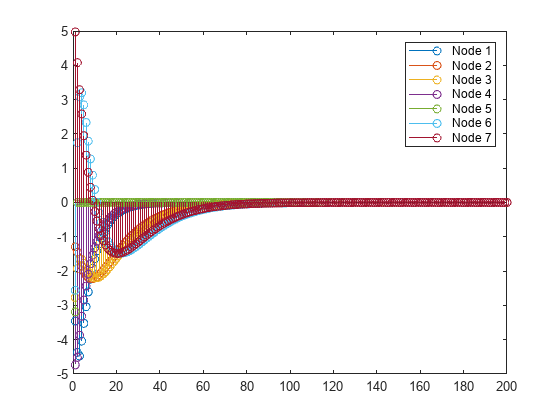

A = [2/7, 0, 0, 5/7, 0, 0, 0;
     1/14, 13/14, 0, 0, 0, 0, 0;
     0, 4/7, 3/7, 0, 0, 0, 0;
     0, 0, 0, 6/7, 1/7, 0, 0;
     0, 0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 0, 3/7, 4/7;
     0, 1/7, 0, 0, 0, 0, 6/7];

% Number of nodes (10)
m = size(A, 1);
% Generate distributed initial conditions randomly in the interval [-5, 5]
x0 = -5 + 10 * rand(m, 1);
% The solution to the concensus equation in discrete time is iterative
x=zeros(m,200);
x(:,1)=x0;
for n=1:199
   x(:,n+1)=A*x(:,n);
end
% Plot the discrete time response for each node

figure
for i = 1:m
    stem(1:200,x(i,:))
    hold on;
end
%}
legend('Node 1','Node 2','Node 3','Node 4','Node 5','Node 6','Node 7');

4. Consider again the undirected graph but a time-varying weighted matrix A(t). Find the consensus protocol and analyze the convergence from a theoretical point of view and in simulation (implement the protocol using Matlab (or Python) and show the results).

When there's a time-varying weighted matrix, the concensus is by the way:

Which can be written as:

$x\left(t\right)$ will converge to a concensus if the matrixes $A\left(t\right)A\left(t-1\right)\ldotp \ldotp A\left(1\right)A\left(0\right)$ converge to a rank one matrix as $t\to \infty$

Using the distributed subgradient method, the concensus - like step :

Followed by a local subgradient step:

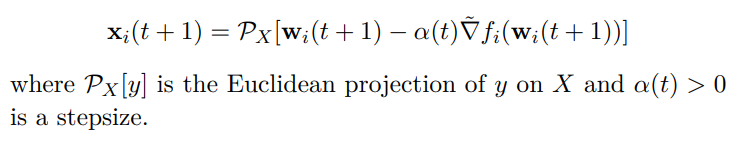

Using a code for the paper "Spectral-like gradient method for distribuited optimization" by Jakovetic, i use a random geometric graph model of 7 nodes.

Firtst, it's necesary to run the Generator_random_Probabilities_Disc_Graph.m, then the generateDataVectorQuadratic.m for finding the xOpt and finally the MainSpectral.m to see the response in time.


$$L_p =\sum_{i=1}^5 \left(f_i \left(x_i \right)+\mu_i \left(x_i -z\right)\right)+\rho {||x_i -z||}_2^2 +g\left(z\right)$$


Setting the randomly the values for $M_i$ and $b_i$ in each state, and treating the conditions in 3 dimensions :


$$\begin{array}{l}
{x_i }^{k+1} =\underset{x}{\arg \;\min \;L_p \left(x_i ,z^k ,\mu^k \right)} =\underset{x}{\arg \;\left(\;\nabla {L_p }_x \right)} =0\\
0=2{M_i }^T \left({{\mathrm{x}}_i M}_i -b_i \right)+\mu_i +2\rho \left({\mathrm{x}}_i -z\right)\\
{x_i }^{k+1} ={\left(2{M_i }^T M_i +2\rho \right)}^{-1} \left({2{M_i }^T b}_i -\mu_i +2\rho z\right)\\
z^{k+1} =\arg \;\min \;L_p \left(x_i^{k+1} ,z,\mu_i^k \right)=\frac{1}{25}\sum_{i=1}^5 \left(x_i^{k+1} +\left(\frac{1}{\rho }\right)\mu_i^k \right)\\
\mu_i^{k+1} =\mu_i^k +\rho \left(x_i^{k+1} -z^{k+1} \right)
\end{array}$$


%parameters
rho=0.6; %arbitrary choice
N=25; %number of nodes
alpha=0.5; %stepsize of gradient ascend 
%Initial conditions
z=zeros(3,100);
%max iteration (100)
mu=zeros(3,N,100); %Initial values for each mu. There's a mu for each restriction xi-z=0
mu(:,:,1)=max(0,rand(3,N,1));
x_=zeros(3,N,100); %0.1+(1-0.1)*random(3,N); % entries in each node in the interval [0.1, 1]
x_(:,:,1)=rand(3,N,1);
M=zeros(3,3,N);
b=zeros(3,N);
M=0.1+(1-0.1).*rand(3,3,N);
b=0.1+(1-0.1).*rand(3,N);
%Error
epsilon=1E-2; %Minimum difference between x and mu
k=1;

while(any(abs(x_(:,:,k)-z(:,k))>epsilon))
    %First, find x(k+1) for all the nodes
    for i=1:N %i for each node
        %for d=1:3 %for each dimension
           
            %1) dim 2) nodo 3) itera -> x, mu
            %1) dim 2) itera -> z
            %1) dim 2) nodo -> b
            %1) row 2) column 3) nodo -> M

            x_(:,i,k+1)=2*(M(:,:,i)'*M(:,:,i)+rho)\(2*M(:,:,i)'*b(:,i)-mu(:,i,k)+2*rho*z(:,k));
        %end 
    end    
      
    for d=1:3 %for each dimension
        z(d,k+1)=(1/N)*(sum(x_(d,:,k+1))+(1/rho)*mu(d,i,k));
    end
    for i=1:N % for each node
      mu(:,i,k+1)=mu(:,i,k)+alpha*(x_(:,i,k+1)-z(d,k+1)); 
      mu(:,i,k+1)=max(0,mu(:,i,k+1));
    end
    k=k+1;  
end
num_it=k-1;
iterations=1:1:num_it;

%plotting
node=18 


agents_1dim=x_(1,node,1:num_it);
agents_2dim=x_(2,node,1:num_it);
agents_3dim=x_(3,node,1:num_it);
plot(iterations,agents_1dim(:))
hold on
plot(iterations,agents_2dim(:))
plot(iterations,agents_3dim(:))
hold off
title("Agents vs Iterations")


This is can be viewev as a Quadratic Programming problem with concensus optimization, i.e:

$\underset{x}{\textrm{mín}} \;\frac{1}{2}x^T Q\;x+q^T x+w=\frac{1}{2}x^T \left(2M\right)x+2\textrm{Mbx}+b^T b$, s.t $\textrm{Ax}\le c$

$\min \;\sum_{i=1}^m f_i \left(x\right)=\min_x \;F\left(x\right)\;$s.t $x-z=0$

It can be reformulated this manner:

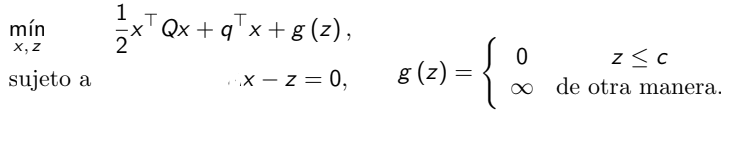

The algorithm considereing an augmented lagrangian is:

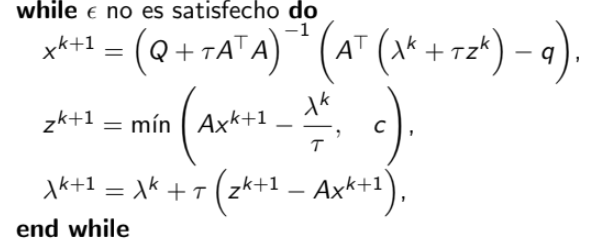


$$x^{k+1} ={\left({2M}^T M+\rho \right)}^{-1} \left(\mu^k +\rho z^k -2\textrm{Mb}\right)$$



$$z^{k+1} =\textrm{mín}\left(x^{k+1} +\frac{\mu^k }{\rho },c\right)$$



$$\mu^{k+1} =\mu^k +\rho \left(z^{k+1} -x^{k+1} \right)$$


%parameters
rho=0.6; %arbitrary choice
N=25; %number of nodes
%Initial conditions
z=zeros(3,500);
%max iteration (100)
mu=zeros(3,N,500); %Initial values for each mu. There's a mu for each restriction xi-z=0
mu(:,:,1)=max(0,rand(3,N,1));
x_=zeros(3,N,500); %0.1+(1-0.1)*random(3,N); % entries in each node in the interval [0.1, 1]
x_(:,:,1)=rand(3,N,1);
M=zeros(3,3,N);
b=zeros(3,N);
M=0.1+(1-0.1).*rand(3,3,N);
b=0.1+(1-0.1).*rand(3,N);
%Error
epsilon=1E-2; %Minimum sidifference between x and mu
%constant
c=1E-2;
k=1;
%any(abs(x_(:,:,k)-z(:,k))>epsilon)
while(any(abs(x_(:,:,k)-z(:,k))>epsilon))
    %First, find x(k+1) for all the nodes
    for i=1:N %i for each node
     
           
            %1) dim 2) nodo 3) itera -> x, mu
            %1) dim 2) itera -> z
            %1) dim 2) nodo -> b
            %1) row 2) column 3) nodo -> M

            x_(:,i,k+1) = (2*M(:,:,i)*transpose(M(:,:,i)) + rho)\(mu(:,i,k)+rho*z(:,k)-2*M(:,:,i)*b(:,i));
            z(:,k+1)=min(x_(:,i,k+1)+mu(:,i,k)/rho,c);
            mu(:,i,k+1)=mu(:,i,k)+rho*(x_(:,i,k+1)-z(:,i));

   
    end    
      
    k=k+1;  
end
num_it=k-1;
iterations=1:1:num_it;

